# Turbulence Regimes

According to [Andrews2005] turbulence regimes are characterized by two quantities: the Rytov variance and the scintillation index. The former is defined as 

$$\sigma_R = 1.23 C_n^2 k^{7/6} L^{11/6}$$,

The Rytov variance is enough to characterize a plane or a spherical wave under turbulence, but it is not in the case of a Gaussian beam. For this last situation, the scintillation index should taken into account. In particular, we can distinguish three turbulation regimes:

- **weak turbulence**, when $\sigma_R < 1$ and $\sigma_I < 1$ throughout the beam profile;

- **moderate turbulence**, when $\sigma_R \sim 1$and $\sigma_I \sim 1$ in the case of a Gaussian beam;

- **strong turbulence**, wheen $\sigma_R > 1$.

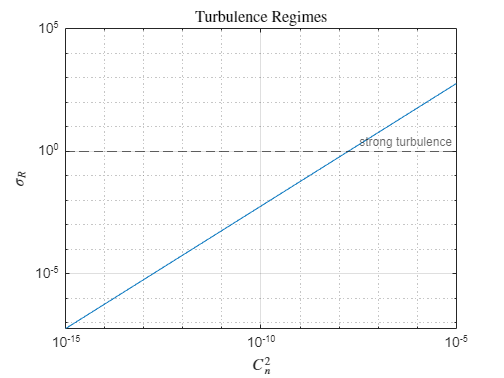

L = 6305;
k = 2*pi/1.55;
Cn2 = 10.^(-15:-5);

sigma_R = 1.23*Cn2*k^(7/6)*L^(11/6);

% Plot Rytov variance as a function of the C_n^2 given the length and the
% wave vector as a parameter
fig = figure();
ax = subplot(1, 1, 1);
plot(Cn2, sigma_R);
yline(1, "--", "strong turbulence");
set(ax, "YScale", "log");
set(ax, "XScale", "log");
xlabel("$C_n^2$");
ylabel("$\sigma_R$");
title("Turbulence Regimes");
grid("on");